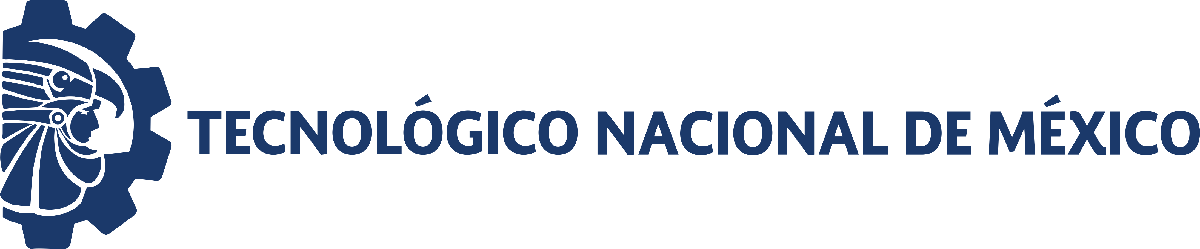                                 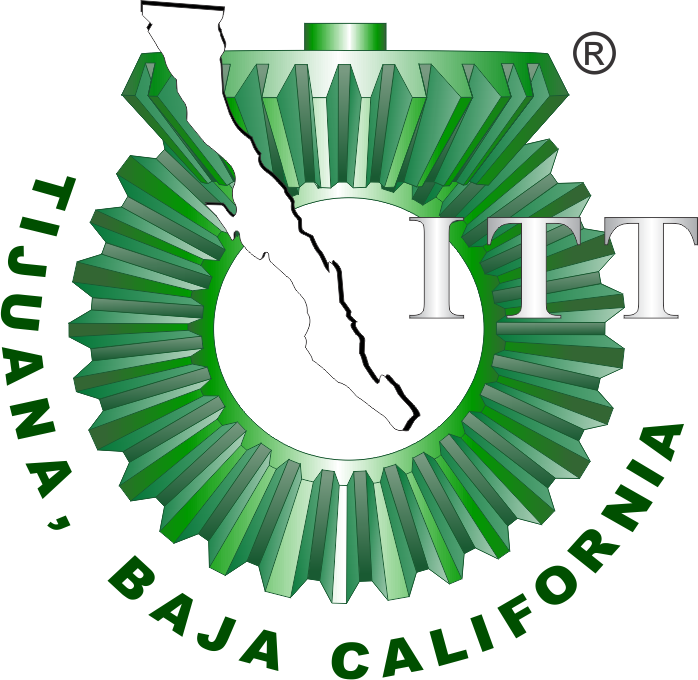

# Práctica tres: Sistema Musculoesqueletico

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

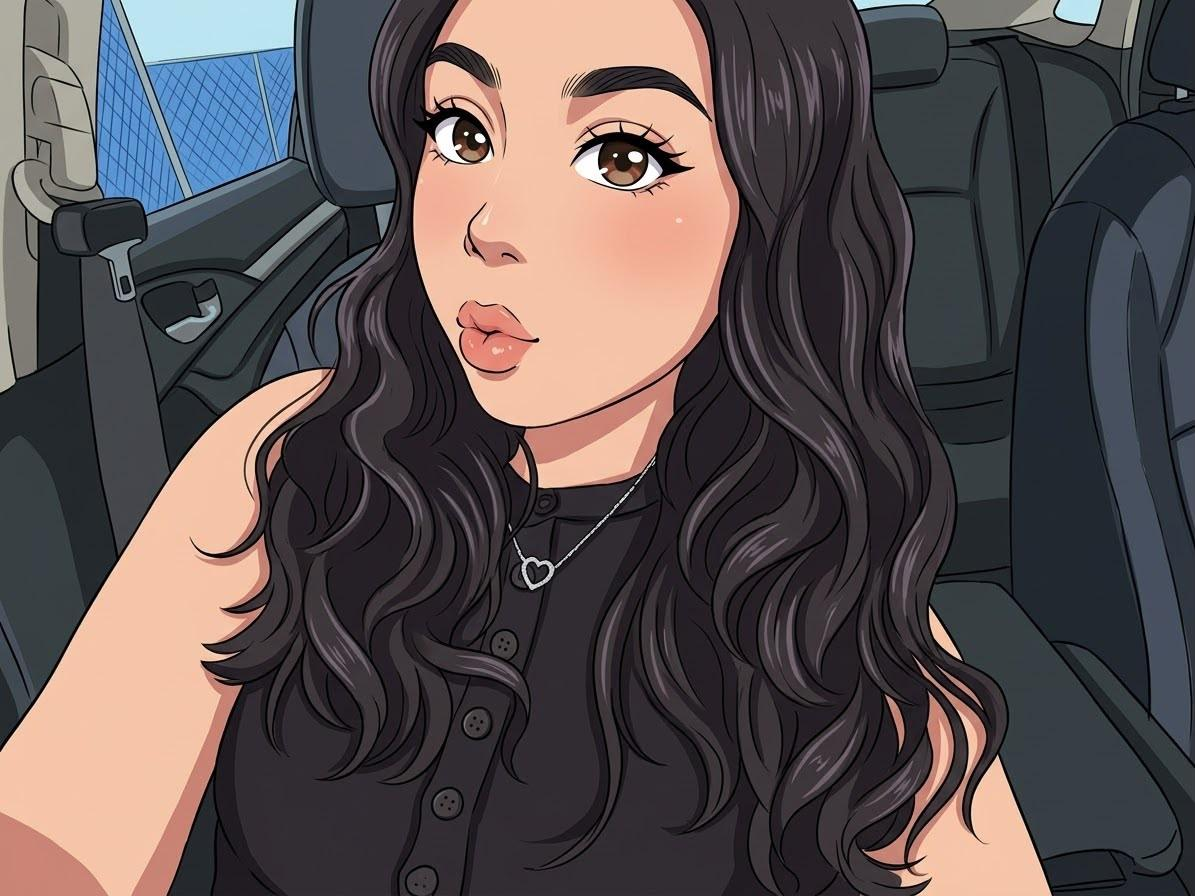

Nombre del alumno: Africa Montserrat Rodriguez Garcia

Número de control: C21211891

Correo institucional: l21211891**@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

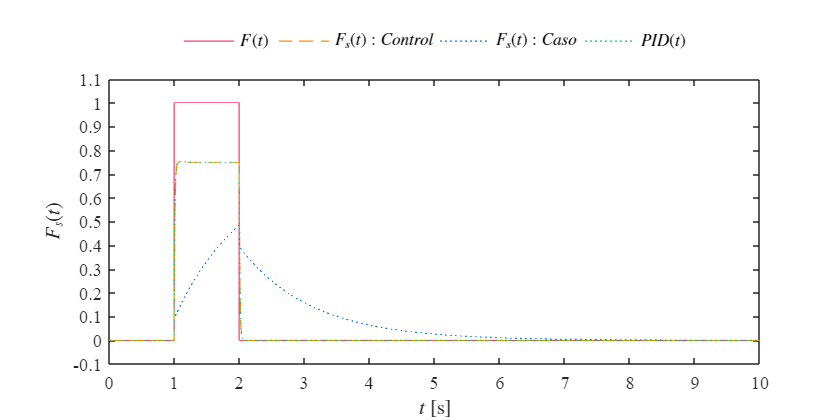

clc; clear; close all; warning('off','all')

tend = 10;

file = 'practica_3';

parameters.StopTime = '10';
parameters.Solver = 'ode15s';
parameters.MaxStep = '1e-3';

x = sim(file,parameters);

plotsignals(x.t,x.F,x.Fsx,x.Fsy,x.PID,'Caso');

## **Modelo de EDOs**

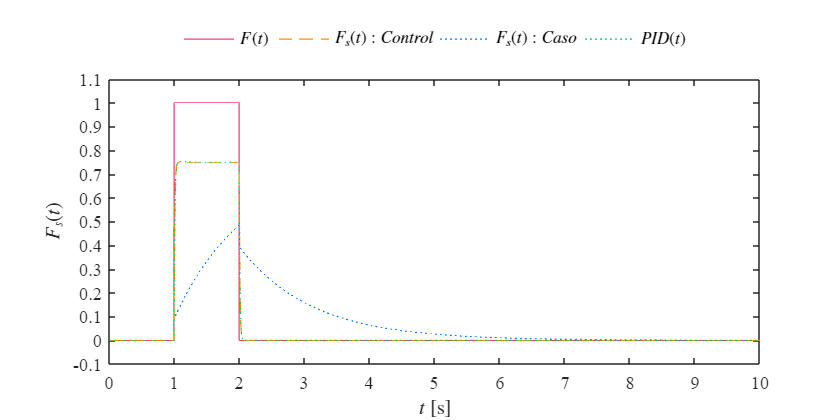


dt = 1e-3;
t = (0:dt:10)';

F = zeros(length(t),1);
F(1/dt:2/dt) = 1;

X_t = x.t;
X_PID = x.PID;

PID = interp1(X_t(:),X_PID(:),t,'previous');

par_control = [0.25,10e-6,100e-6,100];
par_caso = [0.25,10e-6,100e-6,10e3];

Fs_control = musculoesqueletico(par_control,F,t);
Fs_caso = musculoesqueletico(par_caso,F,t);

plotsignals(t,F,Fs_control,Fs_caso,PID,'EDOsys');

## Funcion: Respuesta a la simulacion

function plotsignals(t,x1,x2,x3,x4,caso)

    set(figure(),'color','w')
    set(gcf,'units','inches','position',[1,1,7,3.5])
    set(gca,'fontname','times new roman','fontsize',11)

    hold on; grid off; box on;

    clr1 = [255,60,110]/255;
    clr2 = [255,140,0]/255;
    clr3 = [0,120,255]/255;
    clr4 = [0,205,100]/255;

    plot(t,x1,'-','LineWidth',0.75,'Color',clr1)
    plot(t,x2,'--','LineWidth',0.75,'Color',clr2)
    plot(t,x3,':','LineWidth',0.75,'Color',clr3)
    plot(t,x4,':','LineWidth',0.75,'Color',clr4)

    if strcmp(caso,'Caso')

        L = legend('$F(t)$', ...
                   '$F_s(t):Control$', ...
                   '$F_s(t):Caso$', ...
                   '$PID(t)$');

    elseif strcmp(caso,'EDOsys')

        L = legend('$F(t)$', ...
                   '$F_s(t):Control$', ...
                   '$F_s(t):Caso$', ...
                   '$PID(t)$');

    end

    set(L,'interpreter','latex', ...
          'location','northoutside', ...
          'orientation','horizontal', ...
          'box','off')

    xlabel('$t$ [s]','interpreter','latex')
    ylabel('$F_s(t)$','interpreter','latex')

    xlim([0 10]);
    xticks(0:1:10)

    ylim([-0.1 1.1]);
    yticks(-0.1:0.1:1.1)

end



## Funcion del sistema musculoesqueletico

function Fs = musculoesqueletico(par,F,t)

    alpha = par(1);
    Cs = par(2);
    Cp = par(3);
    R = par(4);

    dt = t(2)-t(1);
    n = length(t)-1;

    x = zeros(length(t),1);
    Fs = zeros(length(t),1);

    for i = 1:n

        x(i+1) = x(i) + ...
        ((F(i)-x(i))/(R*(Cp+Cs)))*dt;

        Fs(i+1) = (Cs*F(i))/(Cp+Cs) + ...
        (1-alpha-Cs/(Cp+Cs))*x(i);

    end

end
